- Figure 4-15 shows a three-node truss element of length *L* and a constant cross-section area *A*. It is made of a material of Young’s modulus *E* and density $\rho$. The truss is subjected to a uniformly distributed force *b*. 

- a) Derive the stiffness matrix for the element.

- b) Write down the expression for the element mass matrix, and obtain $m_{11}$ in terms of *L*, *E*, $\rho$, and *A*. 

- c) Derive the external force vector. 

  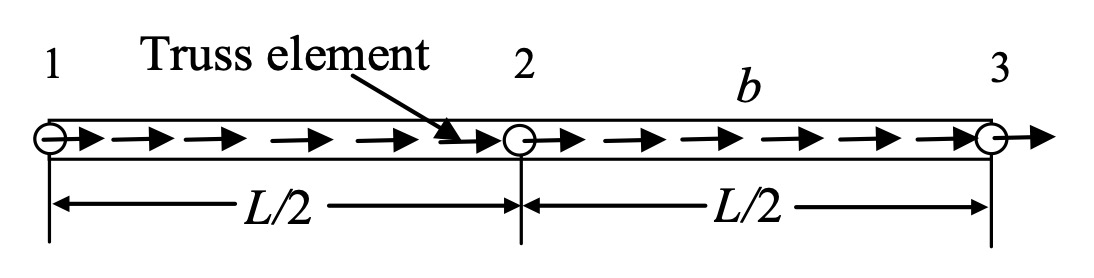

Figure 4-15 A truss element with 3 nodes

#### (a) Derive the stiffness matrix for the element

clear all;clc
syms L x 

The natural coordinate $\xi$ is defined as 


$$\xi =2\frac{x-x_c }{l_e }$$


Where


$$x_c =\frac{L}{2}$$



$$l_e =L$$


x_c = L/2;
l   = L;
xi  = 2 * (x-x_c)/l;

Using the quadradic one-dimensional element with three nodes

 
$$N_1 \left(\xi \right)=-\frac{1}{2}\xi \left(1-\xi \right)$$



$$N_2 \left(\xi \right)=\left(1+\xi \right)\left(1-\xi \right)$$



$$N_3 \left(\xi \right)=\frac{1}{2}\xi \left(1+\xi \right)$$


N1 = -1/2 * xi *(1-xi);
N2 = (1+xi) * (1-xi);
N3 = 1/2 * xi *(1+xi);

N1 = simplify(N1) 

$$N1 = \frac{L^{2}-3\,L\,x+2\,x^{2}}{L^{2}}$$

N2 = simplify(N2) 

$$N2 = \frac{4\,x\,\left(L-x\right)}{L^{2}}$$

N3 = simplify(N3) 

$$N3 = -\frac{x\,\left(L-2\,x\right)}{L^{2}}$$

The strain matrix $B$ has the following form


$$B=\mathrm{LN}=\frac{\partial }{\partial x}\left\lbrack N_1 \left(\xi \right)\;N_2 \left(\xi \right)\;N_3 \left(\xi \right)\right\rbrack$$


which yeilds

N = [N1 N2 N3];

% Derivatives of N1, N2, N3 with respect to xi
dN1_dx = diff(N1);
dN1_dx = simplify(dN1_dx);
dN2_dx = diff(N2);
dN2_dx = simplify(dN2_dx);
dN3_dx = diff(N3);
dN3_dx = simplify(dN3_dx);

% Combine the results into a matrix
dN_dx = [dN1_dx, dN2_dx, dN3_dx];

% Display the result
disp(dN_dx);

$$\left(\begin{array}{ccc} -\frac{3\,L-4\,x}{L^{2}} & \frac{4\,\left(L-2\,x\right)}{L^{2}} & -\frac{L-4\,x}{L^{2}} \end{array}\right)$$

Now that the stain matrix has been obtained, using the stiffness matrix for the truss element can be obtained from


$$k_e =A\int_0^L B^T EBdx$$


which yeilds

B   = dN_dx;
B_T = B.';
BB  = B_T * B;

% Size of BB
[n,m] = size(BB);

% Initialize a symbolic matrix for the integrated values
BB_integrated = sym(zeros(n, m));

% Integrate each element of BB
for i = 1:n
    for j = 1:m
        BB_integrated(i,j) = int(BB(i,j), x, 0, L); % From 0 to L
    end
end

BB_integrated = simplify(BB_integrated); 
%disp(BB_integrated);

#### b) Write down the expression for the element mass matrix, and obtain $m_{11}$ in terms of *L*, *E*, $\rho$, and *A*. 

syms A E
K_e=BB_integrated*A*E

$$K\_e = \begin{array}{l} \left(\begin{array}{ccc} \frac{7\,A\,\text{E}}{3\,L} & \sigma_{1} & \frac{A\,\text{E}}{3\,L}\\ \sigma_{1} & \frac{16\,A\,\text{E}}{3\,L} & \sigma_{1}\\ \frac{A\,\text{E}}{3\,L} & \sigma_{1} & \frac{7\,A\,\text{E}}{3\,L} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{8\,A\,\text{E}}{3\,L} \end{array}$$

The element mass matrix for the three-node truss element can be obtained using the following equation


$$m_e =A\rho \int_0^L N^T Ndx=A\rho \int_0^L \left\lbrack \begin{array}{ccc}
N_1 N_1  & N_1 N_2  & N_1 N_3 \\
N_2 N_1  & N_2 N_2  & N_2 N_3 \\
N_3 N_1  & N_3 N_2  & N_3 N_3 
\end{array}\right\rbrack$$


Integrating yeilds

m_e = [N1*N1 N1*N2 N1*N3;
       N2*N1 N2*N2 N2*N3;
       N3*N1 N3*N2 N3*N3;];

% Size of m_e
[n,m] = size(m_e);

% Initialize a symbolic matrix for the integrated values
m_e_integrated = sym(zeros(n, m));

% Integrate each element of m_e
for i = 1:n
    for j = 1:m
        m_e_integrated(i,j) = int(m_e(i,j), x, 0, L); % From 0 to L
    end
end

m_e_integrated = simplify(m_e_integrated); 
%disp(m_e_integrated);
syms A rho
m_e = m_e_integrated * A * rho

$$m\_e = \left(\begin{array}{ccc} \frac{2\,A\,L\,\rho }{15} & \frac{A\,L\,\rho }{15} & -\frac{A\,L\,\rho }{30}\\ \frac{A\,L\,\rho }{15} & \frac{8\,A\,L\,\rho }{15} & \frac{A\,L\,\rho }{15}\\ -\frac{A\,L\,\rho }{30} & \frac{A\,L\,\rho }{15} & \frac{2\,A\,L\,\rho }{15} \end{array}\right)$$

Where 


$$m_e =A\rho \int_0^L \left\lbrack \begin{array}{ccc}
N_1 N_1  & N_1 N_2  & N_1 N_3 \\
N_2 N_1  & N_2 N_2  & N_2 N_3 \\
N_3 N_1  & N_3 N_2  & N_3 N_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
m_{11}  & m_{12}  & m_{13} \\
m_{21}  & m_{22}  & m_{23} \\
m_{31}  & m_{32}  & m_{33} 
\end{array}\right\rbrack$$


Therefore $m_{11}$ is 

[row, col] = size(m_e);

for i = 1:row
    for j = 1:col
        varName = ['m' num2str(i) num2str(j)];
        eval([varName ' = m_e(i,j);']);
    end
end

disp(m11);

$$\frac{2\,A\,L\,\rho }{15}$$

#### (c) Derive the external force vector

The total nodal force vector for the three-node truss element can be obtained using the following equation


$$f_e =\int_{V_e } N^T f_b dV+\int_{S_e } N^T f_s dS\longrightarrow f_e =\int_{V_e } N^T f_b dV+0$$



$$f_e =Af_x \int_0^L \left\lbrack \begin{array}{c}
N_1 \\
N_2 \\
N_3 
\end{array}\right\rbrack dx$$


N_T = N.';

% Size of N_T
[n,m] = size(N_T);

% Initialize a symbolic matrix for the integrated values
N_T_integrated = sym(zeros(n, m));

% Integrate each element of N_T
for i = 1:n
    for j = 1:m
        N_T_integrated(i,j) = int(N_T(i,j), x, 0, L); % From 0 to L
    end
end

N_T_integrated = simplify(N_T_integrated);
%disp(N_T_integrated)
syms b A
f_e = b*A*N_T_integrated

$$f\_e = \left(\begin{array}{c} \frac{A\,L\,b}{6}\\ \frac{2\,A\,L\,b}{3}\\ \frac{A\,L\,b}{6} \end{array}\right)$$